# Examples for using the `bisection_method` function.

Copyright © 2021 Tamas Kis

## Example #1: Root of a simple function.

*Find the root of *$f\left(x\right)=x^2 -1$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining $f\left(x\right)$,

f = @(x) x^2-1;

We want a root in the interval $\left\lbrack 0,\infty \right)$. Therefore, we use the initial guess $\left\lbrack a,b\right\rbrack =\left\lbrack 0,9999999\right\rbrack$. Finding this root using the bisection method,

x = bisection_method(f,0,9999999)

x = 1.0000

## Example #2: Plot of root estimates at each iteration.

*In Example #1, we found the positive root of *$f\left(x\right)=x^2 -1$* using the bisection method. Now, produce a plot of all root estimates obtained by the *`bisection_method`* function during its solution procedure.*

First, we define $f\left(x\right)$ in MATLAB like before.

f = @(x) x^2-1;

To obtain the root estimates at all iterations, we simply need to define the `opts` structure, set its `return_all` field to `true`, and pass it to the `bisection_method` function. *(Note: we use the same initial guess for the interval as in Example #1).*

opts.return_all = true;
[~,~,x_all] = bisection_method(f,0,9999999,opts);

Plotting the root estimates at each iteration,

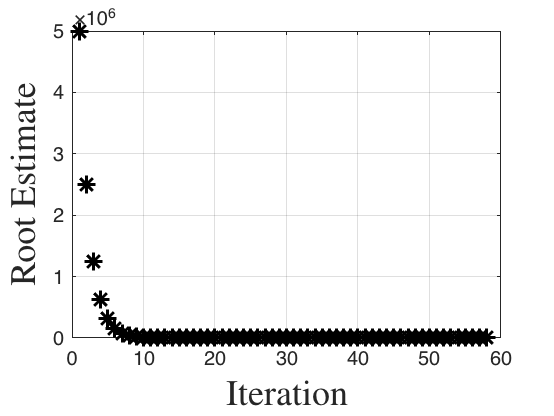

figure;
plot(x_all,'k*','MarkerSize',9,'LineWidth',1.5);
grid on;
xlabel('Iteration','Interpreter','latex','FontSize',18);
ylabel('Root Estimate','Interpreter','latex','FontSize',18);

## Example #3: Intersection of two curves.

*Find the intersection of *$y=x^2$ and $y=\cos \left(x\right)$ *that is in the interval *$\left\lbrack 0,\infty \right)$.

Defining both functions,

y1 = @(x) x.^2;
y2 = @(x) cos(x);

Let's plot both functions to see where their intersection lies.

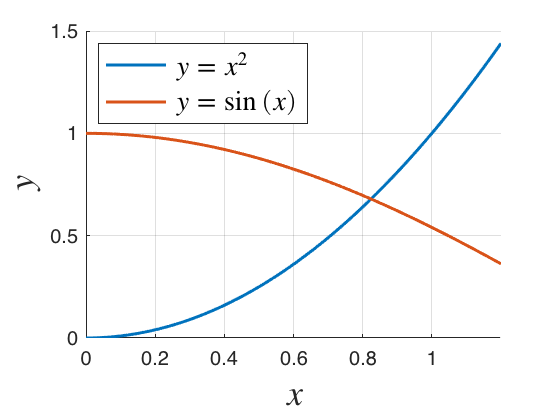

% defines interval for plotting
x = 0:0.01:1.2;

% plot
figure;
hold on;
plot(x,y1(x),'LineWidth',1.5);
plot(x,y2(x),'LineWidth',1.5);
hold off;
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','Interpreter','latex','FontSize',14,...
    'Location','northwest');

Finding the intersection of the two functions is equivalent to finding the *root* of their difference. Therefore, we can use the bisection method on $y=\cos \left(x\right)-x^2$ with an initial guess of $\left\lbrack a,b\right\rbrack =\left\lbrack 0\ldotp 75,0\ldotp 85\right\rbrack$ (picked using the plot above) to find the intersection.

x_int = bisection_method(@(x) y2(x)-y1(x),0.75,0.85)

x_int = 0.8241

Plotting to confirm that this is the true intersection,

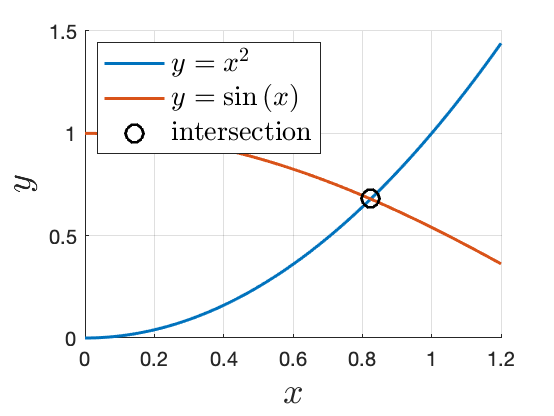

figure;
hold on;
plot(x,y1(x),'LineWidth',1.5);
plot(x,y2(x),'LineWidth',1.5);
plot(x_int,y1(x_int),'ko','MarkerSize',9,'LineWidth',1.5);
hold off;
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$y$','Interpreter','latex','FontSize',18);
legend('$y=x^{2}$','$y=\sin{(x)}$','intersection','Interpreter','latex',...
    'FontSize',14,'Location','northwest');

## Example #4: Root of a more complicated function.

*Find all the roots of *$g\left(x\right)$ in the interval $\left\lbrack 0,20\right\rbrack$ where $g\left(x\right)$ is defined using the following calculation procedure:

- 
$$c=5x^2$$


- 
$$d=\sin \left(\frac{c}{500}\right)$$


- 
$$e=\cosh \left(d\right)$$


- 
$$g=5e^2 +27e-40$$


First, we need to define $g\left(x\right)$. **We define **$g\left(x\right)$** as the MATLAB function **$\texttt{gx}$** at the bottom of this page under "gx Function for Example #4".** To define $g\left(x\right)$ as an anonymous function, we assign it a function handle:

g = @(x) gx(x);

Due to the complexity of $g\left(x\right)$, we have no idea where its root(s) is/are. Therefore, let's first plot $g\left(x\right)$ on $\left\lbrack 0,20\right\rbrack$ (i.e. the interval we want to find the root(s) in).

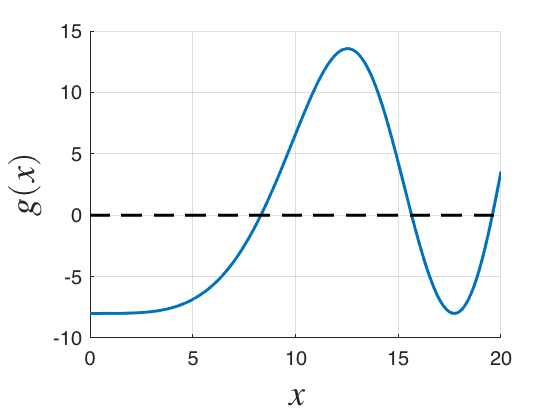

% interval definition
x = 0:0.1:20;

% evaluates g(x) over interval
g_evaluated = g(x);

% plot of g(x) over the interval [-20,20]
figure;
hold on;
plot(x,g_evaluated,'LineWidth',1.5);
plot(x,zeros(size(x)),'k--','LineWidth',1.5);
hold off;
grid on;
xlabel('$x$','Interpreter','latex','FontSize',18);
ylabel('$g(x)$','Interpreter','latex','FontSize',18);

Visually, we can easily identify the following intervals that contain a root:

                    
$$\left\lbrack 8,9\right\rbrack$$


                    
$$\left\lbrack 15,16\right\rbrack$$


                    
$$\left\lbrack 19,20\right\rbrack$$


Solving for the corresponding roots with the bisection method,

root1 = bisection_method(g,8,9)

root1 = 8.3149

root2 = bisection_method(g,15,16)

root2 = 15.6532

root3 = bisection_method(g,19,20)

root3 = 19.5780

## `gx` Function for Example #4

function g = gx(x)
    c = 5*x.^2;
    d = sin(c/500);
    e = cosh(d);
    g = 5*e.^2+27*e-40;
end